# Including conditional State-Jumps into your `IFDIFF` Trajectory

Normally, it is not possible to model conditional state jumps in the solution trajectory of an ODE using only the right-hand side (RHS). However, there are many processes where including such a jump can significantly simplify the underlying model—or is even essential. In these cases, `IFDIFF` offers a convenient workaround that ensures an accurate resulting trajectory while still allowing for the computation of sensitivities over the entire time span. This is done by the `ifdiff_jumpif` condition-function and the `ifdiff_update` jump-function.

## A Bouncing Ball Simulation

As an example we take the bouncing ball problem, an ODE system which models the height `x(1)` and velocity `x(2)` of a ball bouncing on the ground. The RHS looks as follows:


$$\dot{x} = \pmatrix{\dot{x_1} \cr \dot{x_2}} = \pmatrix{\dot{h} \cr \dot{v}} = f(t,x,p) = \pmatrix{x_2 \cr -p_1} = \pmatrix{v \cr -g}\\ 

x_1 = h = \text{height }; \hspace{20pt} x_2 = v = \text{velocity }; \hspace{20pt} p_1 = g = \text{gravity accelleration constant };\\

\text{if } x_1 = 0 \text{ (collision with the ground), place ball above ground and flip velocity: } \hspace{20pt}

\Delta x = \pmatrix{-x_1 + \varepsilon(1) \cdot \frac{p_2^2}{p_1} \cdot x_2^2 \cr -(1 + p_2) \cdot x_2}
$$


initIFDIFF(); type rhsBounceball_cp.m; clear;


function dx = rhsBounceball_cp(~, x, p)
    dx = [x(2); -p(1)];
    if ifdiff_jumpif(x(1), -1)
        deltaH = -x(1) + eps(1)*(1/p(1)) * p(2)^2*x(2)^2;
        deltaV = -(1+p(2))*x(2);
        ifdiff_update([deltaH; deltaV]);
    end
end


`ifdiff_jumpif(arg1, arg2)` checks, whether its first argument $arg_1$ (here: `x(1)`) passes zero. The second argument can be used to determin which passing direction is counted.


$$
arg_2 = \begin{cases}
-1 & ; \text{ positive to negative} \\
0 & ; \text{ both directions} \\
1 & ; \text{ negative to positive}
\end{cases}$$
 

This is extremely helpful in our example, since we want the ball to *"pass"* the ground (height: `x(1) == 0`) only from above. Then, the `ifdiff_jumpif` code block is executed and computes the `ifdiff_update` jump. In this case we set the ball sightly above 0, negate the velocity vector and scale it down a little (we simulate a small loss of energy of the system during the collision).

solver = @ode15s;
options = odeset('AbsTol', 1e-8, 'RelTol', 1e-6);
g     = 9.807;
gamma = 0.9;
v0 = 10;
h0 = eps(1)*(1/g) * v0^2;
p = [g gamma];

This model does not currently account for **Zeno’s phenomenon**, where an infinite number of bounces occur in a finite time, ultimately resulting in the ball coming to rest. In this implementation, we avoid this issue by simply not integrating beyond the time at which the bouncing becomes negligible. A more detailed approach might involve explicitly detecting when the system’s total energy falls below a defined threshold and terminating the simulation accordingly (effectively *"making"* the ball come to rest).

Check this out by adjusting the slider below!

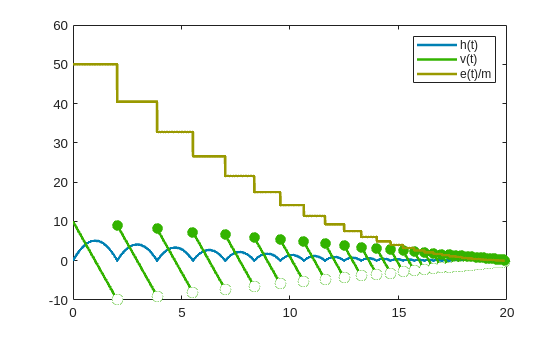

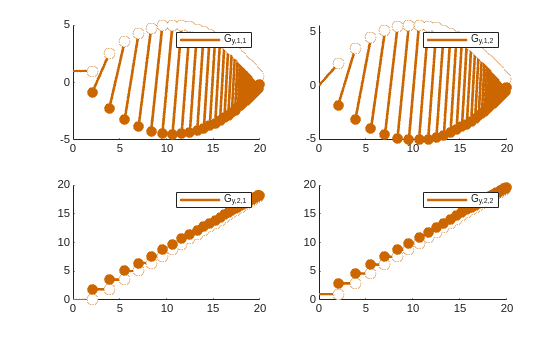

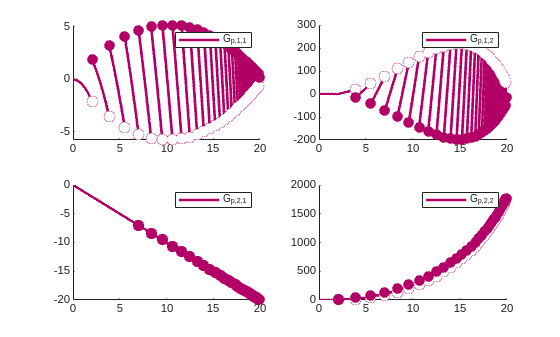

t0 = 0;
tEnd = 19.9;
x0 = [h0; v0];
simulateBouncingBall(t0, tEnd, x0, p, solver, options);